%%INPUTS

%Flight Conditions
h = 0 %ft

h = 0

V = 100; %kts
[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3

AirDens = 0.0024

V=V*1.688

V = 168.8000

AoA = 0;

%Wing Parameters
QuarterSweep = 0 %deg

QuarterSweep = 0

Df = 18;
TaperRatio = 0.6

TaperRatio = 0.6000

S = 1303

S = 1303

b = 118

b = 118

AR = b^2/S

AR = 10.6861

SweepLE = atand(tand(QuarterSweep)-4/AR*((0-0.25)*(1-TaperRatio)/(1+TaperRatio)))

SweepLE = 1.3402

InstallAngle = 2.25

InstallAngle = 2.2500

LiftCurveSlope = 0.0908 %Per deg

LiftCurveSlope = 0.0908


%Prop Parameters
ThrustAngle = 0

ThrustAngle = 0

Rp = 10

Rp = 10

HP = 6830*1.8 %Per engine

HP = 12294

PropEff = 0.81

PropEff = 0.8100

zProp = 3

zProp = 3


%Thrust = HP*0.81/V*550
Thrust = 27666*0.9

Thrust = 2.4899e+04


x1 = 10

x1 = 10

x2 = 10

x2 = 10


ThrustCoef = Thrust/(0.5*AirDens*V^2*S) 

ThrustCoef = 0.5643

PropCorrelationParam = S*ThrustCoef/(8*Rp^2) %Use to find f

PropCorrelationParam = 0.9191

Sp = pi*Rp^2

Sp = 314.1593


%DATCOM Figures
PropNormForceCoeff = 0.5 %Pg 1387 Depends on Nominal Blade Anlgle and # of props

PropNormForceCoeff = 0.5000

PropUpwashGradient = 0.5 %Pg 1275 Depends on AR and Prop Distance from 0.25Cr

PropUpwashGradient = 0.5000

f = 1.75 %Pg 1387 Depends on PropCorrelationParam

f = 1.7500

C1 = 0.4 %Pg 1388 Depends on PropCorrelationParam

C1 = 0.4000

C2 = 0.2 %Pg 1388 Depends on PropCorrelationParam

C2 = 0.2000

K = 1 %Pg 1398 Depends on Si/S

K = 1

K1 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K1 = 0.8000

K2 = 0.8 %Pg 1389 Depends on Prop CorrelationParam, AR, AR immersed

K2 = 0.8000


%For clean wing
daCLmax = 1.2

daCLmax = 1.2000

MaxLiftCoefRatio = 0.9

MaxLiftCoefRatio = 0.9000


%Airfoil Parameters
ZeroLiftAngle = -3

ZeroLiftAngle = -3

ClMax = 1.6

ClMax = 1.6000

AirfoilStallAngle = 16

AirfoilStallAngle = 16

Cla = 0.11

Cla = 0.1100



%Clean wing
CLMax = MaxLiftCoefRatio*ClMax

CLMax = 1.4400

WingStallAngle = CLMax/LiftCurveSlope+ZeroLiftAngle+daCLmax

WingStallAngle = 14.0590


%Flapped From Graphs
FlapDeflec = 40 %Deg

FlapDeflec = 40

ddZeroLiftAngle = -0.45 %For Slotted flaps with cf/c = 0.3 at 40deg deflection

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = ddZeroLiftAngle*FlapDeflec

dZeroLiftAngle = -18


%%CALCULATIONS

%Flapped Wing
y1flap=Df/2

y1flap = 9

y2flap=0.75*b/2

y2flap = 44.2500

y3flap=0

y3flap = 0

y4flap=0

y4flap = 0


cr = 2*S/(b*(1+TaperRatio))

cr = 13.8030


c1flap = cr*(1-(1-TaperRatio)*2*y1flap/b)

c1flap = 12.9608

c2flap = cr*(1-(1-TaperRatio)*2*y2flap/b)

c2flap = 9.6621

c3flap = cr*(1-(1-TaperRatio)*2*y3flap/b)

c3flap = 13.8030

c4flap = cr*(1-(1-TaperRatio)*2*y4flap/b)

c4flap = 13.8030


SWF = 2*((c1flap+c2flap)/2*(y2flap-y1flap) + (c3flap+c4flap)/2*(y4flap-y3flap))

SWF = 797.4547

SweepFactor = (1-0.08*(cosd(QuarterSweep))^2)*(cosd(QuarterSweep))^(3/4)

SweepFactor = 0.9200


dAirfoilStallAngle = -4*10^(-7)*FlapDeflec^4+3*10^(-5)*FlapDeflec^3-0.0019*FlapDeflec^2-0.024*FlapDeflec

dAirfoilStallAngle = -3.1040


AirfoilStallAngleFlapped = AirfoilStallAngle + dAirfoilStallAngle

AirfoilStallAngleFlapped = 12.8960


ZeroLiftAngleFlapped = ZeroLiftAngle + dZeroLiftAngle

ZeroLiftAngleFlapped = -21


ClMaxFlapped = Cla*(AirfoilStallAngleFlapped - ZeroLiftAngleFlapped)

ClMaxFlapped = 3.7286


dClMaxFlapped = ClMaxFlapped - ClMax

dClMaxFlapped = 2.1286

dCLMaxFlapped = dClMaxFlapped*SWF*SweepFactor/S

dCLMaxFlapped = 1.1985


CLMaxFlapped = CLMax + dCLMaxFlapped

CLMaxFlapped = 2.6385


%Powered CLmax



%KN =
KN = 80.7 %ASSUMED

KN = 80.7000


TruePropNormalForceCoeff = PropNormForceCoeff*(1+0.8*(KN/80.7-1))

TruePropNormalForceCoeff = 0.5000


PropPlaneAngle = ThrustAngle + PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)  

PropPlaneAngle = 2.6250


dCLPropNorm = f*TruePropNormalForceCoeff*PropPlaneAngle/57.3*Sp/S*cosd(ThrustAngle)

dCLPropNorm = 0.0097


UpwashGradient = C1 + C2*TruePropNormalForceCoeff

UpwashGradient = 0.5000


PropDownwashAngle = UpwashGradient*PropPlaneAngle

PropDownwashAngle = 1.3125


dWingAoA = -PropDownwashAngle/(1+PropUpwashGradient)

dWingAoA = -0.8750


PropUpwashAngle = PropUpwashGradient*(AoA+InstallAngle-ZeroLiftAngle)

PropUpwashAngle = 2.6250


for x=1:1:27
   
    CL = (x-1)/10
    
    %Inboard Props
    y1 = 19 %ft to centerline of prop
    z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b1 = 2*sqrt(Rp^2-z1^2)
    c1 = cr*(1-(1-TaperRatio)*2*y1/b)
    S1 = b1*c1
    AReff1 = b1/c1
    dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)
    dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1
    dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CL
    
    %Outboard Props
    y2 = 45.5 %ft to centerline of prop
    z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing
    b2 = 2*sqrt(Rp^2-z2^2)
    c2 = cr*(1-(1-TaperRatio)*2*y2/b)
    S2 = b2*c2
    AReff2 = b2/c2
    dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)
    dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1
    dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CL
    
    ImmersedRatio = (2*S1+2*S2)/S
    
    CLPowered(x) = CL + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

    alpha(x) = (CL/LiftCurveSlope)+ZeroLiftAngleFlapped
    
end

CL = 0

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 0.1000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.0327

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.0260

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 0.2000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.0654

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.0519

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 0.3000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.0981

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.0779

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 0.4000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.1308

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.1039

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 0.5000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.1635

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.1298

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 0.6000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.1963

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.1558

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 0.7000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.2290

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.1817

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 0.8000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.2617

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.2077

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 0.9000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.2944

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.2337

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.3271

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.2596

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1.1000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.3598

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.2856

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1.2000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.3925

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.3116

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1.3000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.4252

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.3375

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1.4000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.4579

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.3635

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1.5000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.4906

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.3894

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1.6000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.5233

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.4154

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1.7000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.5560

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.4414

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1.8000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.5888

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.4673

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 1.9000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.6215

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.4933

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 2

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.6542

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.5193

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 2.1000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.6869

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.5452

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 2.2000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.7196

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.5712

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 2.3000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.7523

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.5972

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 2.4000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.7850

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.6231

ImmersedRatio = 0.6267

CLPowered =    -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha =   -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 2.5000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.8177

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.6491

ImmersedRatio = 0.6267

CLPowered = 1×27
   -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.6402


alpha = 1×27
  -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


CL = 2.6000

y1 = 19

z1 = 3.2291

b1 = 18.9286

c1 = 12.0250

S1 = 227.6154

AReff1 = 1.5741

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = -0.0371

dCLq1 = 0.8504

y2 = 45.5000

z2 = 3.2291

b2 = 18.9286

c2 = 9.5451

S2 = 180.6753

AReff2 = 1.9831

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = -0.0294

dCLq2 = 0.6750

ImmersedRatio = 0.6267

CLPowered = 1×27
   -0.0944    0.1229    0.3403    0.5576    0.7750    0.9923    1.2097    1.4270    1.6443    1.8617    2.0790    2.2964    2.5137    2.7311    2.9484    3.1657    3.3831    3.6004    3.8178    4.0351    4.2525    4.4698    4.6871    4.9045    5.1218    5.3392    5.5565


alpha = 1×27
  -21.0000  -19.8987  -18.7974  -17.6960  -16.5947  -15.4934  -14.3921  -13.2907  -12.1894  -11.0881   -9.9868   -8.8855   -7.7841   -6.6828   -5.5815   -4.4802   -3.3789   -2.2775   -1.1762   -0.0749    1.0264    2.1278    3.2291    4.3304    5.4317    6.5330    7.6344


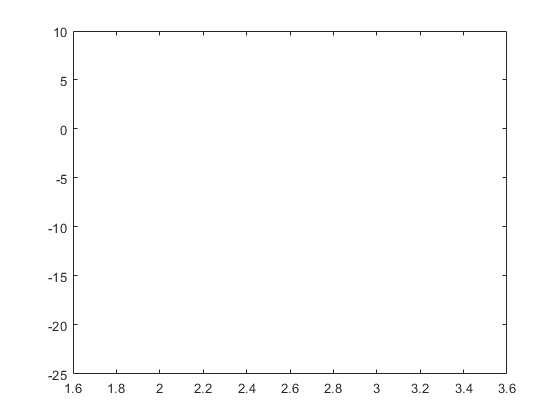


plot(CL,alpha)


%Inboard Props
y1 = 19 %ft to centerline of prop

y1 = 19

z1 = x1*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z1 = 3.2291

b1 = 2*sqrt(Rp^2-z1^2)

b1 = 18.9286

c1 = cr*(1-(1-TaperRatio)*2*y1/b)

c1 = 12.0250

S1 = b1*c1

S1 = 227.6154

AReff1 = b1/c1

AReff1 = 1.5741

dSlipstreamDynPressure1 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure1 = 2.3405

dCLWash1 = (1+dSlipstreamDynPressure1)*S1/S*LiftCurveSlope*dWingAoA*K1

dCLWash1 = -0.0371

dCLq1 = K1*dSlipstreamDynPressure1*S1/S*CLMaxFlapped

dCLq1 = 0.8630


%Outboard Props
y2 = 45.5 %ft to centerline of prop

y2 = 45.5000

z2 = x2*tand(ThrustAngle+PropUpwashAngle-PropDownwashAngle)+zProp %Assuming Prop is in line with MAC on wing

z2 = 3.2291

b2 = 2*sqrt(Rp^2-z2^2)

b2 = 18.9286

c2 = cr*(1-(1-TaperRatio)*2*y2/b)

c2 = 9.5451

S2 = b2*c2

S2 = 180.6753

AReff2 = b2/c2

AReff2 = 1.9831

dSlipstreamDynPressure2 = S*ThrustCoef/(pi*Rp^2)

dSlipstreamDynPressure2 = 2.3405

dCLWash2 = (1+dSlipstreamDynPressure2)*S2/S*LiftCurveSlope*dWingAoA*K1

dCLWash2 = -0.0294

dCLq2 = K2*dSlipstreamDynPressure2*S2/S*CLMaxFlapped

dCLq2 = 0.6850


ImmersedRatio = (2*S1+2*S2)/S

ImmersedRatio = 0.6267


CLMaxPowered = CLMaxFlapped + K*(4*dCLPropNorm + 2*dCLWash1 + 2*dCLq1 + 2*dCLWash2 + 2*dCLq2)

CLMaxPowered = 5.6402